% AAE 421 HW 4 Problem 2
% Tomoki Koike
close all; clear all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
fdir = "C:\Users\Tomo\Desktop\studies\2020-Fall\AAE421\matlab\output\hw4";
addpath(genpath("C:\Users\Tomo\Desktop\studies\2020-Fall\AAE421\matlab\rootlocus"))

% (1)

num = 1;
den = conv([1,0],[1, 1]);
den = conv(den, [1, 10]);
[poles,zrs,angs,sigma,bi_pt,T_P,T_Z,k,w,fig1] = rootLocus_stepBystep_negFeedback(num, den);

poles =      0
   -10
    -1



zrs =

  0×1 empty double column vector



angs =     60   180   300


sigma = -3.6667

bi_pt =    -6.8465
   -0.4869


T_P = 3×3 table
    POLES    RADIUS     DEGREES
    _____    _______    _______

       0      3.1416      180  
     -10     -3.1416     -180  
      -1           0        0  



T_Z =

     []



$$Re = k=11\,w^{2}$$

$$Im = 0=w^{3}-10\,w$$

k =      0
   110
   110


w =          0
   -3.1623
    3.1623


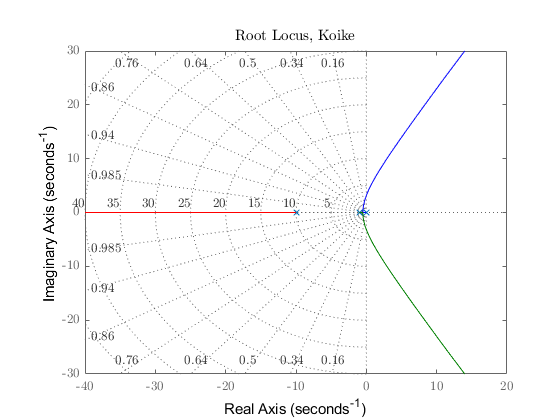

saveas(fig1, fullfile(fdir, "p2_RL.png"));

% (2)

syms sigma omega k omega_n
assume([sigma, omega, k, omega_n], {'real', 'positive'});
s = sigma + omega*1i;
eqn = k == -(s^3 + 11*s^2 + 10*s);
zeta = 0.707;
eqn = subs(eqn, sigma, -zeta*omega_n);
eqn = simplify(subs(eqn, omega, omega_n*sqrt(1-zeta^2)))

$$eqn = {\omega_{n}}^{3}\,\left(0.7074+0.7068\,\mathrm{i}\right)+k={\omega_{n}}^{2}\,\left(0.0033+11.0000\,\mathrm{i}\right)+\omega_{n}\,\left(7.0700-7.0721\,\mathrm{i}\right)$$

eqn_LHS = lhs(eqn);
eqn_LHS_real = real(eqn_LHS);
eqn_LHS_imag = imag(eqn_LHS);
eqn_RHS = rhs(eqn);
eqn_RHS_real = real(eqn_RHS);
eqn_RHS_imag = imag(eqn_RHS);
eqn_real = eqn_LHS_real == eqn_RHS_real;
eqn_imag = eqn_LHS_imag == eqn_RHS_imag;
res1 = solve(eqn_imag, omega_n);
eqn_real = subs(eqn_real, omega_n, res1(1));
res2 = solve(eqn_real, k)

$$res2 = 4.5374$$

eqn_imag

$$eqn\_imag = 0.7068\,{\omega_{n}}^{3}=11.0000\,{\omega_{n}}^{2}-7.0721\,\omega_{n}$$

eqn_real

$$eqn\_real = k+0.2146=4.7521$$

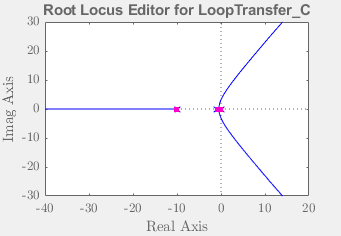

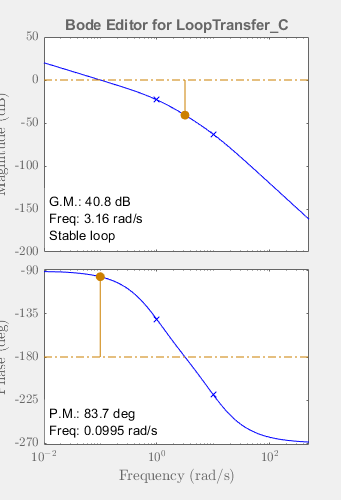

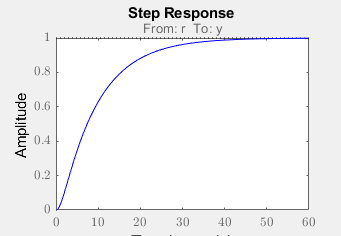

% (5)

sys = tf(num, den);
controlSystemDesigner(sys);